# 数字图像处理 作业9 (第八章)

阮泉源 201930033629

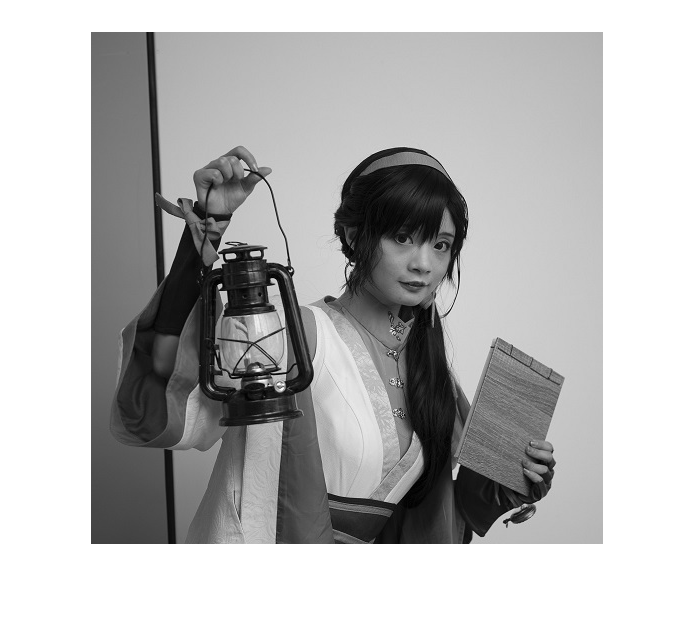

img = imread('coser.jpg');
img = rgb2gray(img);
img = im2double(img);

imshow(img);

[w, h] = size(img);

N = 8;

zonal_encode = zeros(w, h);
thres_encode = zeros(w, h);

dct_zonal = zeros(w, h);
dct_thres = zeros(w, h);

建立区域编码的掩膜，只保留左上角的$\frac{N^2 }{2}$个数。

zonal_mask = zeros(N);
for i=1:N
    if i>N/2
        for j=1:N-i
            zonal_mask(i, j) = 1;
        end
    else
        for j=1:N-i+1
            zonal_mask(i, j) = 1;
        end
    end 
end
disp(zonal_mask);

     1     1     1     1     1     1     1     1
     1     1     1     1     1     1     1     0
     1     1     1     1     1     1     0     0
     1     1     1     1     1     0     0     0
     1     1     1     0     0     0     0     0
     1     1     0     0     0     0     0     0
     1     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0



接下来进行DCT变换，然后分别进行区域编码与阈值编码。

区域编码时，使用8x8的DCT块与掩膜进行点乘运算，取出前50%的系数。

阈值编码时，需要先将DCT块展平为一维向量，然后根据绝对值进行排序，保留该向量绝对值最大的50%个元素，其他元素置零，然后再将这个向量恢复回8x8的DCT块。注意到**取绝对值的操作是必不可少的**，因为有些元素是负值，但如果将这元素视为较小的值的话，会导致逆运算中相位不对称，出现不属于图像中异常的亮点。

获得两个处理后的DCT块后，利用DCT反变换，可以恢复回原始图像。

for i=1:N:w
    for j=1:N:h
        % DCT transfer
        subimg = img(i:i+N-1, j:j+N-1);
        sub_dct = my_dct2dim(subimg);
        
        % by zonal encoding
        sub_dct_zonal_encode = sub_dct.*zonal_mask;
        dct_zonal(i:i+N-1, j:j+N-1) = sub_dct_zonal_encode;
        % inverse DCT transfer
        sub_img_zonal_decode = idct2(sub_dct_zonal_encode);
        zonal_encode(i:i+N-1, j:j+N-1) = sub_img_zonal_decode;
        
        % by threshold encoding
        sub_dct_fattern = reshape(sub_dct, [N*N, 1]);
        % Abs is important! Without abs, the result will be vary different.
        [~, index] = sort(abs(sub_dct_fattern));
        thres_rebulid = zeros(1, N*N);
        for k=1:N*N
            if k<N*N/2
                % set the 50% minimum element to zero
                thres_rebulid(index(k)) = 0;
            else
                % retain the 50% maximum element
                thres_rebulid(index(k)) = sub_dct_fattern(index(k));
            end
        end
        thres_rebulid = reshape(thres_rebulid, [N, N]);
        dct_thres(i:i+N-1, j:j+N-1) = thres_rebulid;
        % inverse DCT transfer
        sub_img_thres_decoder = idct2(thres_rebulid);
        thres_encode(i:i+N-1, j:j+N-1) = sub_img_thres_decoder;
    end
end

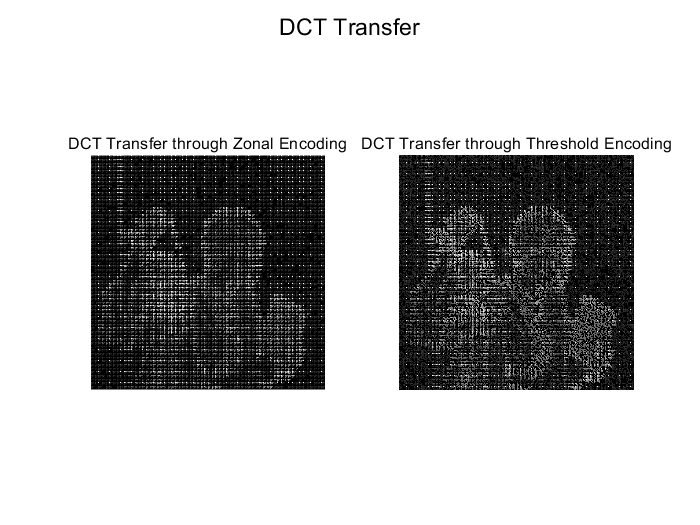

figure;
subplot(1,2,1);
imshow(abs(dct_zonal).^0.3);
title('DCT Transfer through Zonal Encoding');
subplot(1,2,2);
imshow(abs(dct_thres).^0.3);
title('DCT Transfer through Threshold Encoding');
suptitle('DCT Transfer')

计算反变换后的绝对误差，并显示，可以看到，通过阈值编码的结果绝对误差更小，因为阈值编码还需要对位置进行编码，需要使用更多的信息。

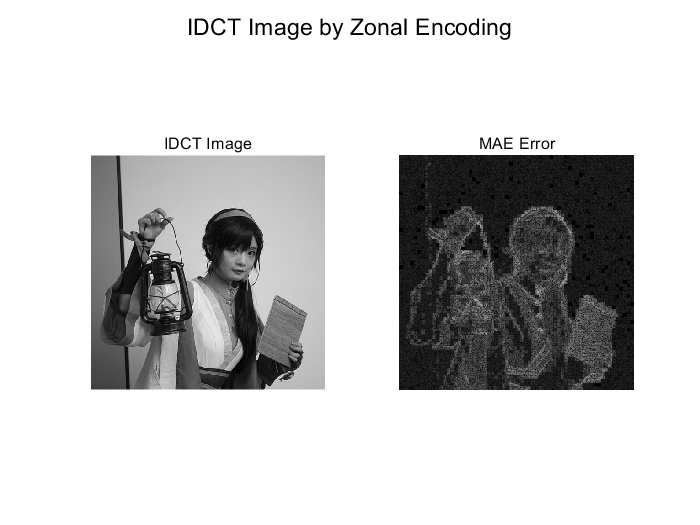

rms_zonal = abs(zonal_encode-img);
figure;
subplot(1,2,1);
imshow(zonal_encode);
title('IDCT Image');
subplot(1,2,2);
imshow((rms_zonal).^0.3);
title('MAE Error')
suptitle('IDCT Image by Zonal Encoding')

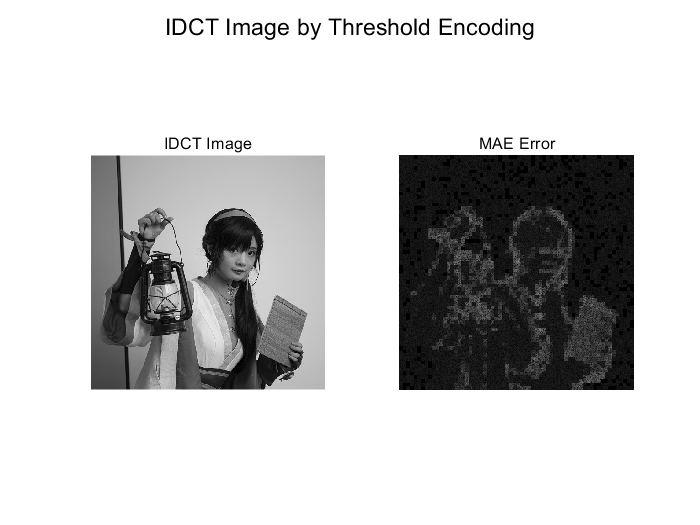

rms_thres = abs(thres_encode-img);
figure;
subplot(1,2,1);
imshow(thres_encode);
title('IDCT Image')
subplot(1,2,2);
imshow((rms_thres).^0.3);
title('MAE Error')
suptitle('IDCT Image by Threshold Encoding')

直观对比两种结果，可以看到两种结果的还原度都还不错，但像头发纹理之类比较细节的内容，区域编码不能够很好地保持。

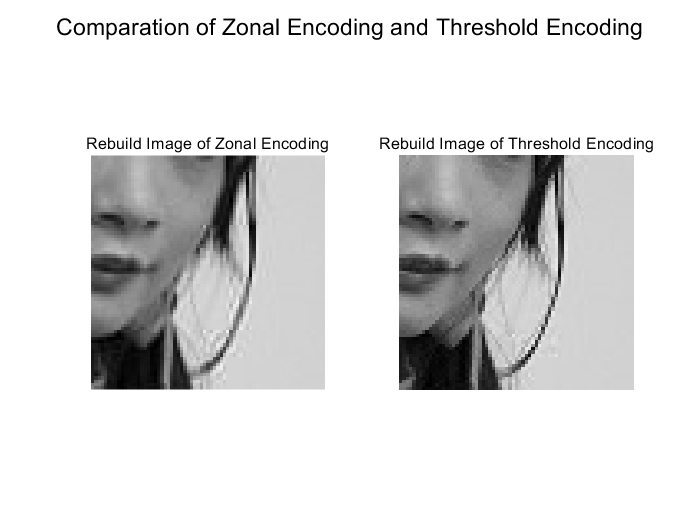

figure;
subplot(1,2,1);
imshow(zonal_encode(220:290, 320:390))
title('Rebuild Image of Zonal Encoding')
subplot(1,2,2);
imshow(thres_encode(220:290, 320:390))
title('Rebuild Image of Threshold Encoding')
suptitle('Comparation of Zonal Encoding and Threshold Encoding')

可以通过两次一维DCT变换实现二维DCT变换。其中dim是dimension的缩写。

function y = my_dct1dim(x)
    % dct transfer in one dimentions
    [N, ~] = size(x);
    y = zeros(N, 1);
    for u=0:N-1
        y(u+1) = cos((1:2:2*N-1)*pi*u/2/N)*x;
        if u==0
            y(u+1) = y(u+1)*sqrt(1/N);
        else
            y(u+1) = y(u+1)*sqrt(2/N);
        end
    end
end


function y = my_dct2dim(x)
    [N, M] = size(x);
    y = zeros(N, M);
    for u=1:N
        y(u,:) = my_dct1dim(x(u,:)')';
    end
    for v=1:N
        y(:,v) = my_dct1dim(y(:,v));
    end
end